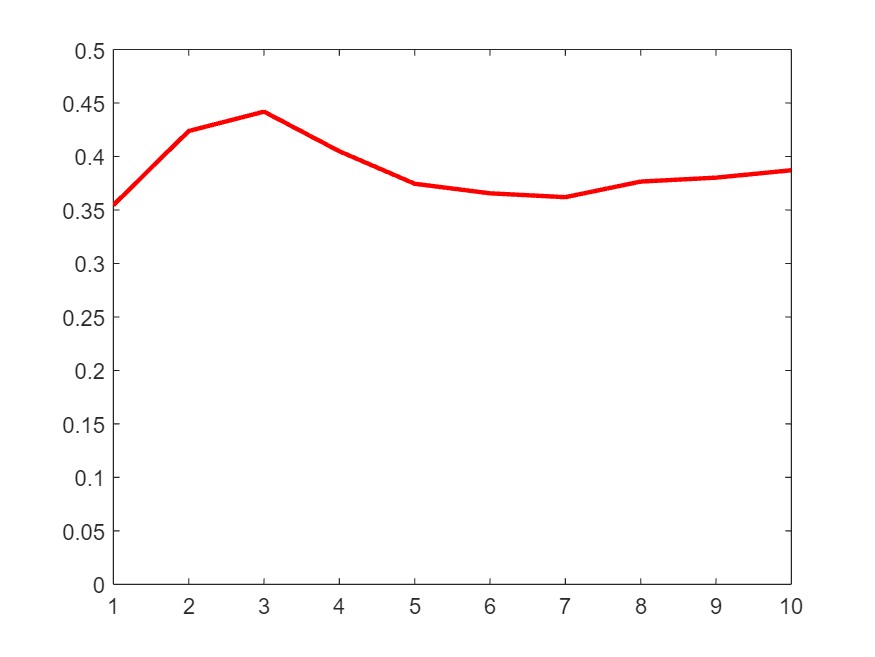

z = [0, 0.39, 0.50, 0.48, 0.29, 0.25, 0.32, 0.34, 0.48, 0.41, 0.45];
s = size(z);
xp = [0]; Pp = [1]; xpp = [0]; Ppp = [1]; K = [0];
A = 1; H = 1; Q = 0; R = 0.1;
for k=2:s(2)
    xp(k) = A*xpp(k-1);
    Pp(k) = A*Ppp(k-1)*A' + Q;
    K(k) = Pp(k)*H/(H*Pp(k)*H + R);
    xpp(k) = xp(k) + K(k)*(z(k) - H*xp(k));
    Ppp(k) = (1 - K(k)*H)*Pp(k);
end

plot(1:s(2)-1, xpp(2:s(2)), 'r', 'LineWidth', 2);
hold on;
axis([1 s(2)-1 0 0.5]);